# Programming Assignment: Random Sampling Methods

## INTRODUCTION

In this assignment you will be writing a program to help guide a six link robot shown in the figure below from one configuration to another while avoiding the objects in the workspace. This assignment will give you some experience working with planning methods based on random sampling. The robot shown in the figure below is comprised of six revolute links and its configuration can be specified with a vector (*θ*1,*θ*2,*θ*3,*θ*4,*θ*5,*θ*6) where each entry is an angle between 0 - 360 degrees.

 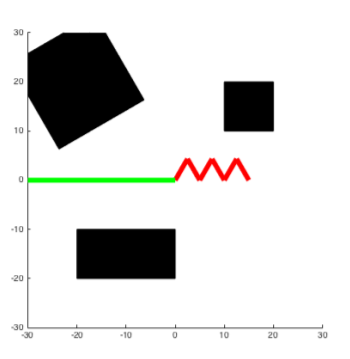

## **CONCEPT**

In the previous assignment, you designed a path planning algortihm based on a configuration space for a robotic arm moving in two dimensions. The same concept can be extrapolated to multiple dimensions as well. However, with increasing the number of dimensions, the complexity of the configuration space increases just as much, not to mention the severe increase in the computation power.

As an alternative, the points in the configuration space can be chosen randomly instead of uniformly. On every iteration, the system will choose a configuration in the configuration space at random, and tests whether it is in free space using the collision check function. On achieving success, the configuration is added to the list of other points to form a path between the start and goal.

## **IMPLEMENTATION**

Your main job for this assignment is to complete the PRM function which computes a probabilistic road map of the configuration space.

The input arguments to this function are explained below: 

- `RandomSample`: a function which returns a random sample in freespace. 

- `Dist`: a function which can be used to compute the distance between a given random sample and all of the samples generated so far 

- `LocalPlanner`: a function that can be used to test whether two configuration space points, `x1` and `x2`, can be joined by a straight line. That is LocalPlanner (`x1, x2`) will only return true if the straight line between `x1` and `x2` does not intersect any configuration space obstacles. 

- `nsamples`: the total number of random samples to be generated 

- `k`: number of neighboring samples to be considered during PRM construction.

## **ALGORITHM**

The section of code that you are asked to complete should perform the following steps: 

- Use the array distances generated by Dist function to determine the indices of the k nearest neighbors. (Hint: you may find the sort function useful here.) 

- For each of those neighbors, it should determine whether or not it can forge a path between those two locations using the LocalPlanner function. 

-  If a path exists, it should then update the set of edges as follow:  

Add an entry to edges array indicating the indices of the two samples that have just been joined. 

Add a corresponding entry to the edge lengths array indicating the length of this new edge. 

Increment the nedges variable to reflect the fact that a new node has been added.

These edges and edge lengths constitute a graph which will be used later by the `ShortestPathDijkstra` routine to plan paths through the roadmap. 

NOTE: 

- The number of samples have been predefined to 100 samples since the code becomes computationally expensive with further samples and causes the online grader to timeout. If you wish to see use a greater number of samples, please download the skeleton code from the link below, plug in your code and the new sample number (`nsamples`) in `SixLinkPRMScript.m`

- The image displayed as an output displays the configuration of the robot at one particular point (midway between total set of configurations). If you wish to see the complete animation, please download the skeleton code from the link below and plug in your code in `PRM.m`

% Drawing the robot
% The SixLinkRobot function computes layout of all of the links in the
% robot as a function of the 6 configuration space parameters. You can
% adjust these sixe numbers to see what happens.
fv = SixLinkRobot([-120 120 -120 120 -120 60]);
fv2 = SixLinkRobot([0 0 0 0 0 180]);
p = patch(fv);
p.FaceColor = 'red';
p.EdgeColor = 'none';
p2 = patch(fv2);
p2.FaceColor = 'green';
p2.EdgeColor = 'none';
sz = 30;
axis equal;
axis(sz*[-1 1 -1 1]);

% Add obstacles
obstacle = boxFV(10, 20, 10, 20);
obstacle = appendFV(obstacle, boxFV(-20, 0, -20, -10));
obstacle = appendFV(obstacle, transformFV(boxFV(-10, 10, -10, 10), 30, [-20 20]));
patch(obstacle);

% Build roadmap
nsamples = 100;
neighbors = 5;
roadmap = PRM(@()(RandomSampleSixLink(obstacle)), @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), nsamples, neighbors);

nsamples = 2, nedges = 1
nsamples = 3, nedges = 1
nsamples = 4, nedges = 1
nsamples = 5, nedges = 4
nsamples = 6, nedges = 5
nsamples = 7, nedges = 7
nsamples = 8, nedges = 11
nsamples = 9, nedges = 14
nsamples = 10, nedges = 19
nsamples = 11, nedges = 22
nsamples = 12, nedges = 23
nsamples = 13, nedges = 26
nsamples = 14, nedges = 31
nsamples = 15, nedges = 36
nsamples = 16, nedges = 39
nsamples = 17, nedges = 42
nsamples = 18, nedges = 43
nsamples = 19, nedges = 44
nsamples = 20, nedges = 48
nsamples = 21, nedges = 53
nsamples = 22, nedges = 57
nsamples = 23, nedges = 60
nsamples = 24, nedges = 64
nsamples = 25, nedges = 67
nsamples = 26, nedges = 69
nsamples = 27, nedges = 73
nsamples = 28, nedges = 77
nsamples = 29, nedges = 79
nsamples = 30, nedges = 81
nsamples = 31, nedges = 85
nsamples = 32, nedges = 89
nsamples = 33, nedges = 92
nsamples = 34, nedges = 95
nsamples = 35, nedges = 97
nsamples = 36, nedges = 101
nsamples = 37, nedges = 104
nsamples = 38, nedges = 106
nsamples = 3

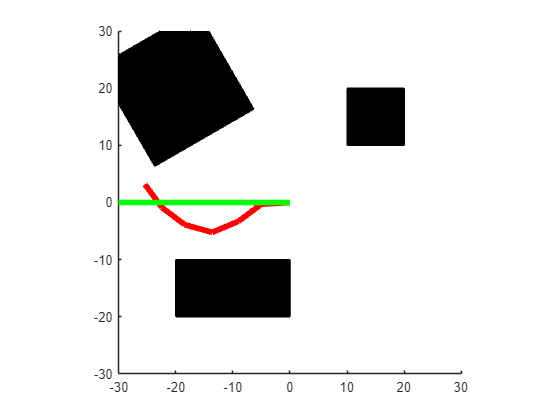


% Add nodes
roadmap2 = AddNode2PRM([240 120 240 120 240 60]', roadmap, @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), neighbors);
roadmap2 = AddNode2PRM([0 0 0 0 0 180]', roadmap2, @DistSixLink, @(x,y)(LocalPlannerSixLink(x,y,obstacle)), neighbors);

% Plan a route
route = ShortestPathDijkstra(roadmap2.edges, roadmap2.edge_lengths, nsamples+1, nsamples+2);

% Plot the trajectory
for i = 2:length(route)
    x1 = roadmap2.samples(:,route(i-1));
    x2 = roadmap2.samples(:,route(i));
    delta = x2 - x1;
    t = delta > 180;
    delta(t) = delta(t) - 360;
    t = delta < -180;
    delta(t) = delta(t) + 360;
    n = ceil(sum(abs(delta)) / 10);
    for j = 0:n/2
        x = mod(x1 + (j/n)*delta, 360);
        fv = SixLinkRobot (x);
        p.Vertices = fv.vertices;
        drawnow;
        if (CollisionCheck(fv, obstacle))
           fprintf (1, 'Ouch\n');
        end
    end
end

function roadmap = PRM(RandomSample, Dist, LocalPlanner, nsamples, k)
    % PRM - ProbablisticRoadMap : This procedure computes a probabilistic road
    % map of configuration space. It relies on 3 functions
    % RandomSample which generates the coordinate vector for a random sample in
    % free space. Dist which measures the distance between two
    % coordinate vectors and LocalPlanner which decides whether two samples are
    % connected.
    %
    % Inputs :
    %
    %   RandomSample : A function that returns a random sample in freespace
    %
    %   Dist : A function that computes the distance between a given point in
    %        configuration space and all of the entries in an array of samples
    %
    %   LocalPlanner :  A function that determines whether there is a collision
    %        free straight line path between two points in configuration space
    %
    %   nsamples : The number of random samples to generate
    %
    %   k : The number of neighbors that should be considered in
    %        forming the roadmap graph.
    %
    % Output :
    %   roadmap - a structure the samples, the edges and edge lengths in the
    %        roadmap graph
    
    x = RandomSample();
    
    % Array of random samples, each column corresponds to the coordinates
    % of a point in configuration space.
    samples = repmat(x(:), 1, nsamples);
    
    % edges - an array with 2 columns. Each row has two integer entries
    % (i, j) which encodes the fact that sample i and sample j are connected
    % by an edge. 
    edges = zeros(nsamples*k, 2);
    edge_lengths = zeros(nsamples*k, 1);
    
    % nedges - this integer keeps track of the number of edges we
    % have in the graph so far
    nedges = 0;
    
    for i = 2:nsamples
        % Note that we are assuming that RandomSample returns a sample in
        % freespace
        x = RandomSample();
    
        samples(:, i) = x(:);
        
        % Find the nearest neighbors
        
        % Here we assume that the Dist function can compute the
        % distance to multiple samples corresponding to the columns of
        % the second argument
        % at the end of this call the array distances will indicate the
        % distance between the new sample and each of the samples that has been
        % generated so far in the program.
        distances = Dist(x, samples(:,1:(i-1)));
        
        %%% YOUR CODE HERE
        [sorted, inds] = sort(distances);
        for j = 1:min(length(sorted), k)
            if LocalPlanner(samples(:, inds(j)), x)
                nedges = nedges + 1;
                edges(nedges, :) = [i, inds(j)];
                edge_lengths(nedges) = distances(inds(j));
            end
        end
        
        % Find the closest k samples, use the LocalPlanner function to see if
        % you can forge an edge to any of these samples and update the edges,
        % edge_lengths and nedges variables accordingly.
        fprintf(1, 'nsamples = %d, nedges = %d\n', i, nedges);
    end
    
    roadmap.samples = samples;
    roadmap.edges = edges(1:nedges, :);
    roadmap.edge_lengths = edge_lengths(1:nedges);
end